# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina Jara

### Edwin Alexander Casallas Moreno

##  Modelo cinemático inverso *fanuc LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* fanuc LR Mate 200 ib, Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..*

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

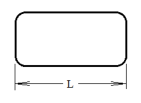

### Características y modelo del robot

Busque información t´ ecnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el siguiente:

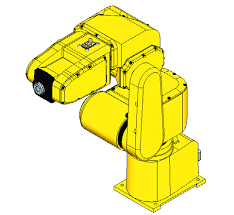

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB posee una capacidad de carga de 7Kg

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB hace parte de la gama de mini robots que buscan emular las longitudes de un brazo humano, por lo que su alcance máximo es de 717mm

En su punto máximo suerior logra 970mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 770mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.01 mm.

#### 5. Gráfica(s) de espacio alcanzable.

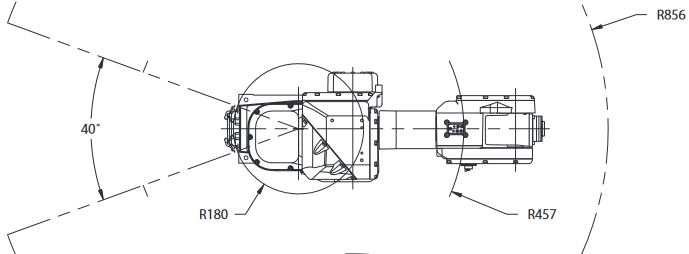

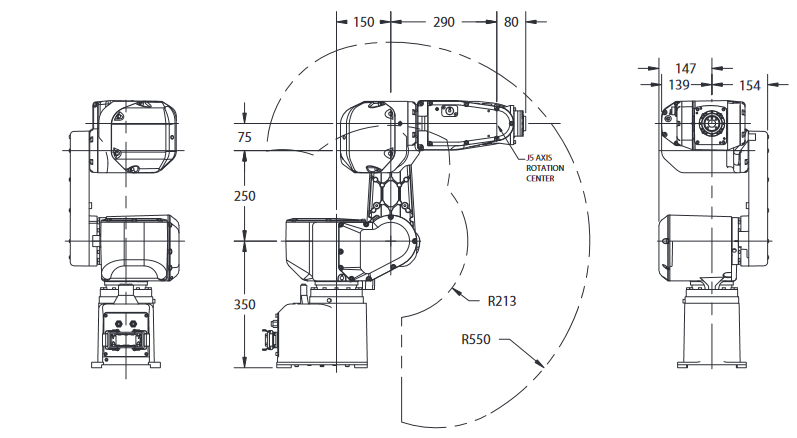

#### 6. Tabla de parámetros DH.

# 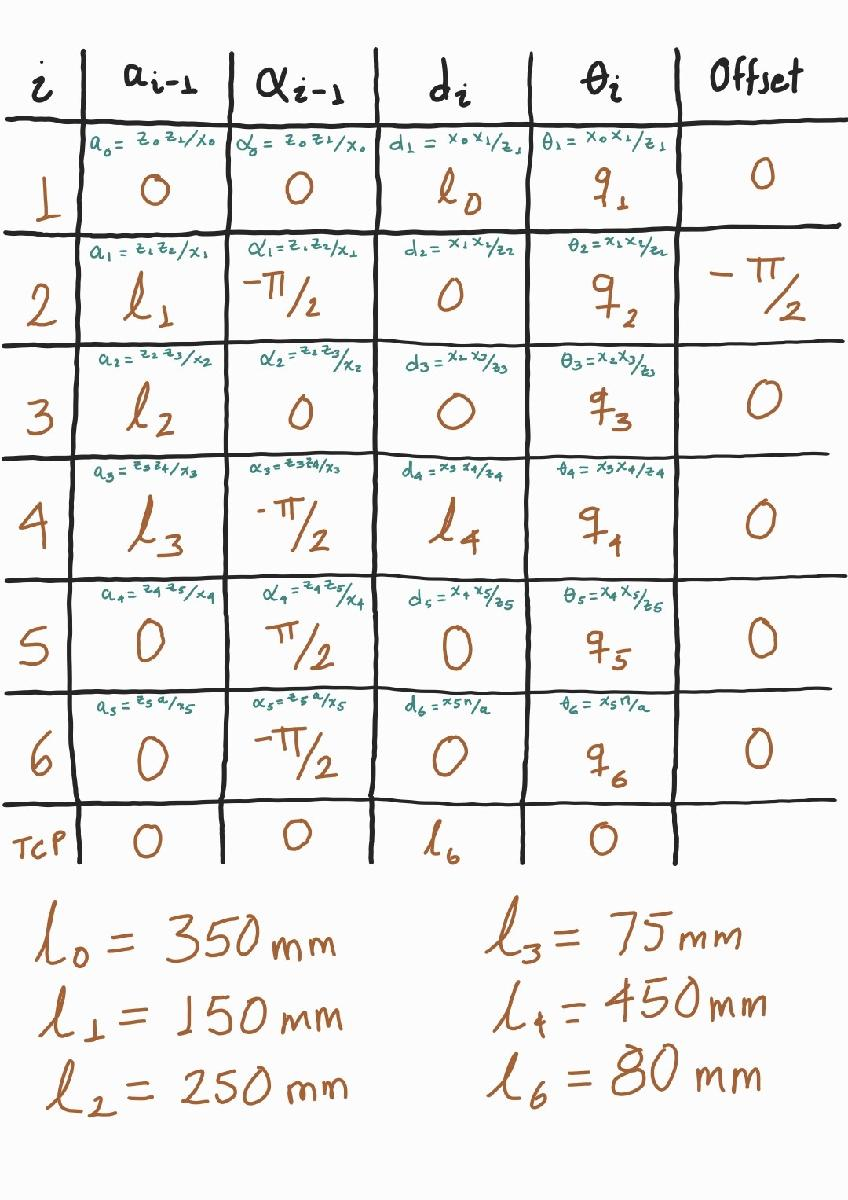

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

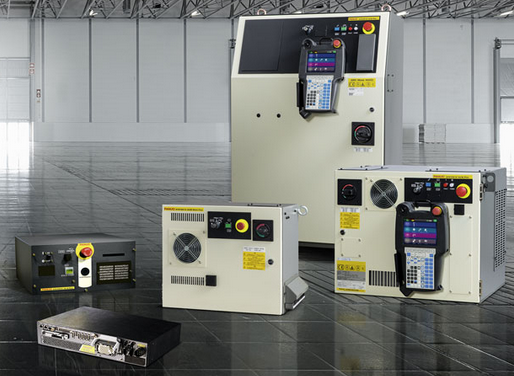

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion:

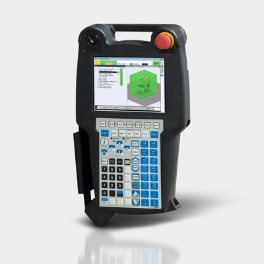

### Modelos

#### Peter Corke

l0 = 0.35;
l1 = 0.15;
l2 = 0.25;
l3 = 0.075;
l4 = 0.45;
l6 = 0.08;

ws = [-70 80 -70 80 -20 70]/10;
plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };

L(1) = Link('revolute', 'a', 0, 'alpha', 0, 'd', l0, 'offset', 0, 'qlim', ...
    [-2*pi/3 2*pi/3], 'modified');
L(2) = Link('revolute', 'a', l1, 'alpha', -pi/2, 'd', 0, 'offset', -pi/2, 'qlim', ...
    [-pi pi], 'modified');
L(3) = Link('revolute', 'a', l2, 'alpha', 0, 'd', 0, 'offset', 0, 'qlim', ...
    [-2*pi/3 2*pi/3], 'modified');
L(4) = Link('revolute', 'a', l3, 'alpha', -pi/2, 'd', l4, 'offset', 0, 'qlim', ...
    [-2*pi/3 2*pi/3], 'modified');
L(5) = Link('revolute', 'a', 0, 'alpha', pi/2, 'd', 0, 'offset', 0, 'qlim', ...
    [-2*pi/3 2*pi/3], 'modified');
L(6) = Link('revolute', 'a', 0, 'alpha', -pi/2, 'd', 0, 'offset', 0, 'qlim', ...
    [-2*pi/3 2*pi/3], 'modified');

Robot_Fanuc = SerialLink(L, 'name', 'FANUC LR Mate 200iB', 'plotopt', plot_options)

 
Robot_Fanuc = 
 
FANUC LR Mate 200iB (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.35|          0|          0|          0|
|  2|         q2|          0|       0.15|     -1.571|     -1.571|
|  3|         q3|          0|       0.25|          0|          0|
|  4|         q4|       0.45|      0.075|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|          0|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0      

%%
Robot_Fanuc.tool = [ 0  0   1  l6;...
               1  0   0  0 ;...
               0  1   0  0 ;...
               0  0   0  1  ];

%%
q = [0 0 0 0 0 0];

Robot_Fanuc.teach(q)

%%
hold on
trplot(eye(4),'length',2 )

%% Solucion problena geometrico directo
TCP = Robot_Fanuc.fkine(q)

TCP =     0.0000    1.0000    0.0000    0.6000
   -1.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000    0.7550
         0         0         0    1.0000


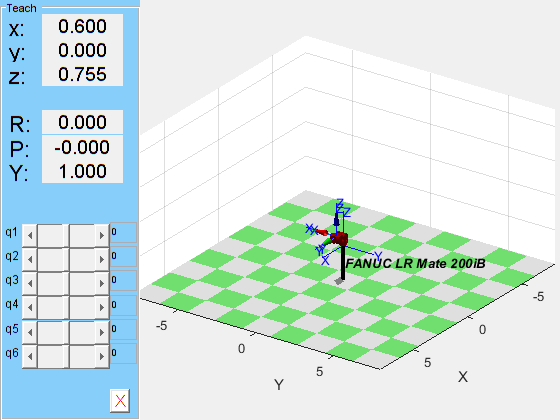

trplot(TCP,'length',2 )

tr2rpy(TCP,'zyx','deg')

ans =   -90.0000    0.0000   -0.0000



%% para las trayectorias se emplea:
T0=transl(0.4,0.2,0) * trotx(pi);
T1=transl(-0.4,-0.2,0.3) * troty(pi/2);
T = ctraj(T0, T1, 50);
T(:,:,1) %primera pose

ans =     1.0000         0         0    0.4000
         0   -1.0000         0    0.2000
         0         0   -1.0000         0
         0         0         0    1.0000


T(:,:,10) %decima pose

ans =     0.9859    0.1670    0.0141    0.3393
    0.1670   -0.9717   -0.1670    0.1696
   -0.0141    0.1670   -0.9859    0.0228
         0         0         0    1.0000


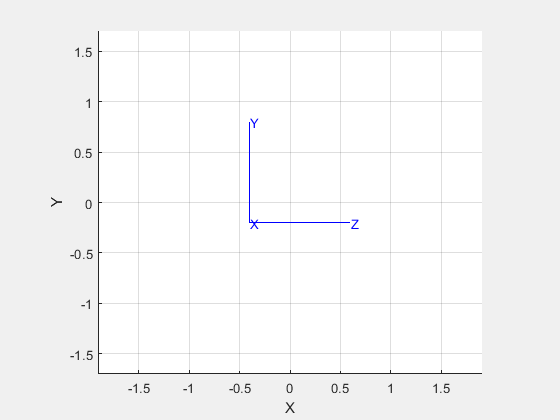

clf; tranimate(T)

### Robotics Systems Toolbox (RST) de MATLAB®

Se comienza cargando el robot FANUC LR Mate 200*i*B con la ayuda de la función *loadrobot()* del *RST*, esto crea un objeto tipo *rigidBodyTree* con las características geométricas del manipulador.

FANUCLRMate200iB = loadrobot('fanucLRMate200ib', 'DataFormat', 'row', 'Gravity', [0 0 -9.81])

Se establece la posición de *home* por defecto del robot como la configuración actual.

currentJointConfig = homeConfiguration(FANUCLRMate200iB);

Se obtiene el número de articulaciones y se rescata el nombre del elemento que representa al efector final.

numJoints = numel(currentJointConfig);
endEffector = 'tool0';

Se especifica el tiempo de paso de la trayectoria y la velocidad aproximada deseada de la herramienta.

timeStep = 0.2; % s
toolSpeed = 0.5; % m/s

Se configuran las poses iniciales y finales del efector final.

jointInit = currentJointConfig;
taskInit = getTransform(FANUCLRMate200iB, jointInit, endEffector)
taskFinal = trvec2tform([0.7 0 0.4])*axang2tform([0 1 0 pi])

## Generaración de la Trayectoria en el Espacio de Trabajo

Se computa primero la distancia que recorrerá la herramienta en la trayectoria.

firstDistance = norm(tform2trvec(taskFinal) - tform2trvec(taskInit))

Luego, se definen los tiempos de la trayectoria basados en la distancia y en la velocidad de la herramienta deseada.

initTime = 0;
finalTime = (firstDistance/toolSpeed) - initTime;
trajTimes = initTime: timeStep: finalTime;
timeInterval = [trajTimes(1) trajTimes(end)]

Se interpola entre las tramas inicial y final de la herramienta para computar los puntos vía (*waypoints*) intermedios en el espacio de trabajo.

[taskWaypoints, taskVelocities] = transformtraj(taskInit, taskFinal, timeInterval, trajTimes)
rotations = tform2quat(taskWaypoints)
translations = tform2trvec(taskWaypoints)
plotTransforms(translations, rotations)

## Control de Movimiento en el Espacio de Trabajo

Se crea un modelo en el espacio de las articulaciones para un control PD en las articulaciones. 

tsMotionModel = taskSpaceMotionModel('RigidBodyTree', FANUCLRMate200iB, 'EndEffectorName', endEffector)

Se establecen las ganancias proporcional y derivativa sobre la orientación en cero, de manera que este comportamiento contralado solo siga la referencia de la posición.

tsMotionModel.Kp(1: 3, 1: 3) = 0;
tsMotionModel.Kd(1: 3, 1: 3) = 0;

Se definen los estados iniciales (posiciones y velocidades de las articulaciones).

q0 = currentJointConfig;
qd0 = zeros(size(q0));

Se utiliza un solucionador de ecuaciones diferenciales ordinarias (ODE) que mejor se acomode al problema del control de movimiento del manipulador. Debido a la simplicidad de este procedimiento en cuanto a la complejidad de la ODE, se hace uso de la función *ode45()*.

[timeTask, stateTask] = ode15s(@(t, state) derivative(tsMotionModel, state, taskInit, zeros(6, 1)), timeInterval, [q0 qd0])

## Generar la Trayectoria en el Espacio de las Articulaciones

Se crea la cinemática inversa del objeto para el robot.

invKin = inverseKinematics('RigidBodyTree', FANUCLRMate200iB)
invKin.SolverParameters.AllowRandomRestart = false;
linkWeights = [1 1 1 1 1 1];

Se calcula la configuración inicial y final deseada para las articulaciones usando la cinemática inversa. Se hace una restricción para que la interpolación se encuentre sobre el dominio mínimo.

initialGuess = jointInit
jointFinal = invKin(endEffector, taskFinal, linkWeights, initialGuess)

wrappedJointFinal = wrapToPi(jointFinal)

Se interpola usando una función polinomial cúbica para generar un arreglo de configuraciones de articulaciones equidistantes.

ctrlPoints = [jointInit' wrappedJointFinal']
jointConfigArray = cubicpolytraj(ctrlPoints, timeInterval, trajTimes)
jointWayPoints = bsplinepolytraj(jointConfigArray, timeInterval, 1)

Control de la Trayectoria en el Espacio de las Articulaciones

Se crea un modelo de control PD sobre el modelo de movimiento de las articulaciones. 

jsMotionModel = jointSpaceMotionModel('RigidBodyTree', FANUCLRMate200iB, 'MotionType', 'PDControl')

Se configura el estado inicial (velocidades y posiciones de las articulaciones)

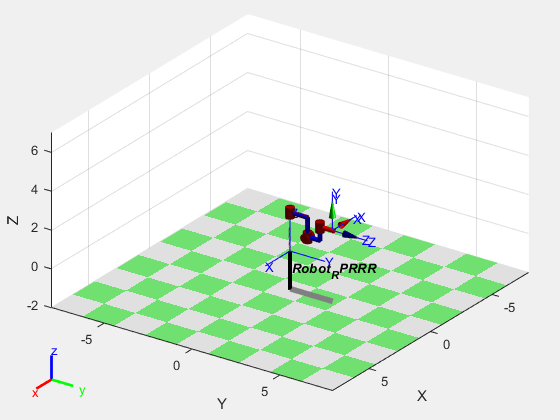

Error using loadrobot (line 46)
Expected robotName to match one of these values:

'abbIrb120', 'abbIrb120T', 'kinovaGen3', 'kinovaJacoJ2N6S200', 'kinovaJacoJ2N6S300', 'kinovaJacoJ2N7S300', 'kinovaJacoJ2S6S300', 'kinovaJacoJ2S7S300', 'kinovaJacoTwoArmExample', 'kinovaMicoM1N4S200', 'kinovaMicoM1N6S200', 'kinovaMicoM1N6S300', 'rethinkBaxter', 'willowgaragePR2'

The input, 'fanucLRMate200ib', did not match any of the valid values.

q0 = currentJointConfig
qd0 = zeros(size(q0))